DataStruct = load('Data.mat');

rng('default');
%Train_idx = DataStruct.Train_indx;
%Test_idx = DataStruct.Test_indx;
Data = DataStruct.a;
labels = DataStruct.classes;

The available data cannot represent a dense sampling for this high dimensional space. If we assumed both data classes were Guassian Distributed, then in general, for one dimension we need minimum 30 randomly selected samples to provide a sufficient dense sampling and for two dimensions we need minimum${30}^2$ randomly selected samples to provide a sufficient dense sampling. For the provided data, we have 100 dimensions, so we need ${30}^{100}$ samples to provide a sufficient dense sampling. In general, we need ${30}^d$ number of samples where d is number of measurment dimensions.

Randomly partition the data into training and test sets

[train_set, test_set, train_labels, test_labels] = train_test_split(0.25, Data, labels);
disp(size(train_set));

   250   100




%{
train_set = Data(Train_idx,:);
test_set = Data(Test_idx,:);
train_labels = labels(Train_idx);
test_labels = labels(Test_idx);
%}

% find index of ones and zeros for both train and test
class1_trainIdx = find(train_labels);
class2_trainIdx = find(~train_labels);
class1_testIdx = find(test_labels);
class2_testIdx = find(~test_labels);

% find data for class 1 and class 2 in train dataset
class1_train = train_set(class1_trainIdx,:);
class2_train = train_set(class2_trainIdx,:);

Use the training data to construct a Principal Component Analysis (PCA) approach to reduce the data to 3 dimensions and apply to test data

% perform PCA on train data
[W_PCA, train_mu, train_cov, PCA_train] = PCA(train_set,3);
PCA_test = (test_set - train_mu)*W_PCA;
disp(size(PCA_test));

   750     3



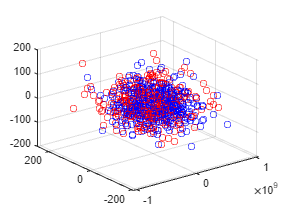


% separate class1 and class2 test set
True_class1 = find(test_labels);
True_class2 = find(~test_labels);

%plot
scatter3(PCA_test(class1_testIdx,1),PCA_test(class1_testIdx,2),PCA_test(class1_testIdx,3),'red');
hold on
scatter3(PCA_test(class2_testIdx,1),PCA_test(class2_testIdx,2),PCA_test(class2_testIdx,3), 'blue');
hold off

Apply Bayes classification on the dimensionality reduced test data. As we can observe from the predictions and confusion matrix, Bayes classifier is not doing well with accuracies fluctuating from 50% to 60% .This is due to PCA's bad performance on some specific cases of scatters between class and within class of the dataset, which will be disscused in the next section. Prediction results are flucating because of randmly split of train and test dataset without stratifying.

% calculate probability of each class
num_class1 = sum(train_labels(:) == 1);
num_class2 = sum(train_labels(:) == 0);
num_train = length(PCA_train);
prob_class1 = num_class1/num_train;
prob_class2 = num_class2/num_train;

% get train data of ones and zeros given indices
PCA_class1_train = PCA_train(class1_trainIdx,:);
PCA_class2_train = PCA_train(class2_trainIdx,:);

% calculate mean and covariance of each class
PCA_class1_mu = mean(PCA_class1_train);
PCA_class2_mu = mean(PCA_class2_train);
PCA_class1_cov = cov(PCA_class1_train);
PCA_class2_cov = cov(PCA_class2_train);

% create discriminant function
PCA_g1 = Discriminant(PCA_test, PCA_class1_mu', PCA_class1_cov, prob_class1);
PCA_g2 = Discriminant(PCA_test, PCA_class2_mu', PCA_class2_cov, prob_class2);

% predict and then compare with true test labels
Pred_class1 = find(PCA_g1>PCA_g2);
Pred_class2 = find(PCA_g2>PCA_g1);

% compare predictions and true labels
diff1_idx = ismember(Pred_class1,True_class1);
diff2_idx = ismember(Pred_class2,True_class2);

% calculate accuracy 
acc = (length(find(diff1_idx))+length(find(diff2_idx)))/750;

% construct confusion matrix
TP = length(find(diff1_idx));
TN = length(find(diff2_idx));
FP = length(find(~diff1_idx));
FN = length(find(~diff2_idx));
PCA_Confusion = [TP FN;FP TN];

disp('Confusion matrix after PCA: ')

Confusion matrix after PCA: 


disp(PCA_Confusion)

    35   292
    37   386



disp('Accuracy after PCA: ')

Accuracy after PCA: 


disp(acc*100)

   56.1333



PCA is not always a correct apporach to apply for addressing classification problems, because PCA cannot recognize scatters between classes and within classes. If scatters within classes are larger than scatters between classes, than PCA is not a good approach for dimensionality reduction.

Use the training data to construct a Fisher Linear Discriminant and use the learned discriminant to reduce the test data to one dimension

% perform FLD
[FLD_train, W_FLD] = FLD(train_set, class1_train, class2_train, 1);
FLD_test = (test_set - train_mu)*W_FLD;
disp(size(FLD_test));

   750     1



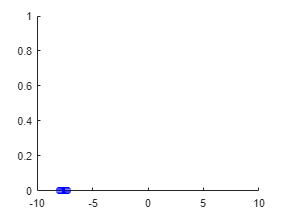


%plot
scatter(FLD_test(class1_testIdx),test_labels(True_class1),'red');
hold on
scatter(FLD_test(class2_testIdx),test_labels(True_class2),'blue');
hold off

Apply Bayes classification on the dimensionality reduced test data. The performance of FLD Bayes is much better than PCA Bayes, because FLD can recognize scatters between classes and within classes. We can also observe not only from confusion matrix and accuracies but also the plots. We can clearly observe that FLD have better performance in separating two classes.

% get train data of ones and zeros given indices
FLD_class1_train = FLD_train(class1_trainIdx,:);
FLD_class2_train = FLD_train(class2_trainIdx,:);

% calculate mean and covariance of each class
FLD_class1_mu = mean(FLD_class1_train);
FLD_class2_mu = mean(FLD_class2_train);
FLD_class1_var = var(FLD_class1_train);
FLD_class2_var = var(FLD_class2_train);

% create discriminant function
FLD_g1 = Single_Discriminant(FLD_test, FLD_class1_mu, FLD_class1_var, prob_class1);
FLD_g2 = Single_Discriminant(FLD_test, FLD_class2_mu, FLD_class2_var, prob_class2);

% predict and then compare with true test labels
Pred_class1_FLD = find(FLD_g1>FLD_g2);
Pred_class2_FLD = find(FLD_g2>FLD_g1);

% compare predictions and true labels
diff1_idx_FLD = ismember(True_class1, Pred_class1_FLD);
diff2_idx_FLD = ismember(True_class2, Pred_class2_FLD);

% construct confusion matrix
TP_FLD = length(find(diff1_idx_FLD));
TN_FLD = length(find(diff2_idx_FLD));
FP_FLD = length(find(~diff1_idx_FLD));
FN_FLD = length(find(~diff2_idx_FLD));
FLD_Confusion = [TP_FLD FN_FLD;FP_FLD TN_FLD];

disp('Confusion matrix after FLD: ')

Confusion matrix after FLD: 


disp(FLD_Confusion)

   327     0
     0   423




% calculate accuracy 
acc = (length(find(diff1_idx_FLD))+length(find(diff2_idx_FLD)))/750;
disp('Accuracy after FLD: ');

Accuracy after FLD: 


disp(acc*100);

   100



As we discussed, above the major differences between FLD and PCA are FLD can recognize scatters between classes and within classes by taking eigendecomposistions of scatter matrix; whereas, PCA only takes eigendecomposistions of covariance matrix, so it can only pick the most representative for the whole dataset not each class.

Increase in train data size does not help improve PCA, becuase an increase in data size does not signifcantly change the largest eigenvalue and corresponding eigenvector. PCA still cannot recognize scatters between and within classes. We confirm this conclusion with experiments using self-implemented train_test_split functions.

net = patternnet(10);
net.inputs{1}.processFcns;
net.trainParam.showWindow = false;
[net,tr] = train(net,train_set.' ,train_labels);
test_pred = net(test_set.');
perf = perform(net,test_labels,test_pred)

perf = 5.8142e-07

diff = sum(abs(round(test_pred)-test_labels))

diff = 0

% compare predictions and true labels


% calculate accuracy 
acc = (750-diff)/750;

disp('Accuracy after NN: ')

Accuracy after NN: 


disp(acc*100)

   100



By removing min-max normalization preprocessing, there is not min-max scaler to normalize weights of each data point. For data points with higher values will have higher weights and have larger (too much) influence on predictions. With normalizations, this influence will be emlimnated with each data point become a ratio relatively to minimum and maximum values.

[train_set, test_set, train_labels, test_labels] = train_test_split(0.25, Data, labels);

n = patternnet();
n.inputs{1}.processFcns = {};
n = configure(n,train_set.',train_labels);
%initialize the network weights
n = init(n);

n.trainParam.showWindow = false;
[n,tr] = train(n,train_set.' ,train_labels);
test_pred_12 = n(test_set.');
perf = perform(n,test_labels,test_pred_12)

perf = 0.8292

diff = sum(abs(round(test_pred_12)-test_labels))

diff = 362

% compare predictions and true labels


% calculate accuracy 
acc = (750-diff)/750;


disp('Accuracy of question 12: ')

Accuracy of question 12: 


disp(acc*100)

   51.7333



Neural Nets can learn patterns from existing data, then apply the patterns on new unseen data and predict. If new datasets "behave" differently from exsting data, than Neural Nets will have bad performance. Moreover, Neural Nets need as much information as possible from exsting dataset. In comparisons, Fisher approaches aim to reduce dimensions and find a lower-dimensional representation of the orginal dataset. In other words, it keeps useful information and removes redundant information. So Neural Nets' problem domains are images and videos pattern recogintions which have or need dataset with high number of dimensions. In comparison, Fisher approaches have the function to reduce dimensions and aim to solve problems like curse of dimensionality and feature extractions. This would continue to hold for non-linearly separable problem domains. However, one thing need to notice is that both PCA and FLD are linear dimensionality reduction methods, so performing both methods on non-linearly separable dataset will not make the dataset linearly separable.

The performance of neural network on the data with the Fisher feature vector removed is poor (acc=~55%), comparing to the same model on the original data (acc=100%). It aligns with our expectation because the feature vector identified through the Fisher analysis is the most informative vector that can represent the original classes. As we discussed above, Neural Nets need as much onformation as possible to predict. If we remove the feature vector, Neural Nets will show bad performances.

[FLDc_train, W_FLDc] = FLD_c(train_set, class1_train, class2_train, 99);
FLDc_test = (test_set - train_mu)*W_FLDc;
disp(size(FLDc_test));

   750    99



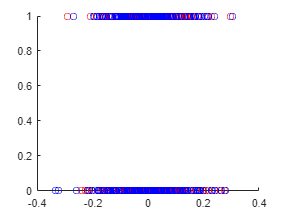


%plot
scatter(FLDc_test(class1_testIdx),test_labels(True_class1),'red');
hold on
scatter(FLDc_test(class2_testIdx),test_labels(True_class2),'blue');
hold off

n = patternnet;
n = configure(n,FLDc_train.',train_labels);
%initialize the network weights
n = init(n);

n.trainParam.showWindow = false;
[n,tr] = train(n,FLDc_train.' ,train_labels);
test_pred_14 = n(FLDc_test.');
perf = perform(n,test_labels,test_pred_14)

perf = 1.1299

diff = sum(abs(round(test_pred_14)-test_labels))

diff = 339

% compare predictions and true labels


% calculate accuracy 
acc = (750-diff)/750;


disp('Accuracy of question 14: ')

Accuracy of question 14: 


disp(acc*100)

   54.8000



It is rare in operational data analysis settings for dense data samplings to be available a priori. Therefore, the selection of of measurement features is crucial. Techniques like PCA, and FLD are handy in these cases. And the choices of different techniques depends on the characteristics of the data, such as the within-class variances and the between-class variances.

Functions

% train test split functions

function [train, test, train_y, test_y]=train_test_split(ratio, dataset, y)
    s = size(dataset);
    m = s(1);
    rand_idx = randperm(m);
    train_idx = rand_idx(1:round(ratio*m));
    test_idx = rand_idx(round(ratio*m)+1:end);
    train = dataset(train_idx,:);
    test = dataset(test_idx,:);
    train_y = y(train_idx);
    test_y = y(test_idx);
end

% PCA function
function [w, mu, Covar, pca_train]=PCA(train,n_dim)
    mu = mean(train); %average
    Covar = cov(train); %covarinace

    % Peform eigenvalue/eigenvector decomposition
    [v,d] = eig(Covar);
    [ d_sorted , idx_sorted ] = sort( diag( d ) , 'descend' );

    % n-dimensional projection
    w = v(:,idx_sorted(1:n_dim));
    pca_train = (train - mu)*w;
end

% function for discriminant analysis
function gi = Discriminant(x, mu, sigma, prob)
    % caluclate terms for discriminat function separatly
    inv_sigma = inv(sigma);
    cap_w = -1/2*inv_sigma;
    w = inv_sigma*mu;
    w_const = -1/2*(mu.')*inv_sigma*mu - 1/2*log(det(sigma)) + log(prob);
    
    % create discriminant function
    gi = dot((x*cap_w).',x.') + (w.')*x.' + w_const;
end

% FLD function
function [transformed_train_FLD, w_FLD]=FLD(train, C1_train,C2_train,n_dim)
    N_class1 = length(C1_train);
    N_class2 = length(C2_train);

    % mean for train dataset, class1 and class2 train dataset 
    m_train = mean(train);
    m1 = mean(C1_train);
    m2 = mean(C2_train);

    % scatter matrix
    S1 = (C1_train-m1)'*(C1_train-m1);
    S2 = (C2_train-m2)'*(C2_train-m2);
    % scatter within class
    Sw = S1 + S2;
    % scatter between class
    Sb = N_class1*((m1 - m_train)'*(m1 - m_train)) + N_class2*((m2 - m_train)'*(m2 - m_train));
    
    % Peform eigenvalue/eigenvector decomposition
    [v_FLD,d_FLD] = eig(Sb, Sw);
    [d_sorted_FLD , idx_sorted_FLD] = sort( diag(d_FLD) , 'descend' );

    % n-dimensional projection
    w_FLD = v_FLD(:,idx_sorted_FLD(1:n_dim));
    transformed_train_FLD = (train - m_train)*w_FLD;
end

% single variate gaussian discriminant function
function gi = Single_Discriminant(x, mu, var, proba)
    gi = zeros(1,length(x));
    for i=1:length(x)
        val = -((norm(x(i)-mu))^2)/var+log(proba);
        gi(i) = val;
    end
end

function [transformed_train_FLD, w_FLD]=FLD_c(train, C1_train,C2_train,n_dim)
    N_class1 = length(C1_train);
    N_class2 = length(C2_train);

    % mean for train dataset, class1 and class2 train dataset 
    m_train = mean(train);
    m1 = mean(C1_train);
    m2 = mean(C2_train);

    % scatter matrix
    S1 = (C1_train-m1)'*(C1_train-m1);
    S2 = (C2_train-m2)'*(C2_train-m2);
    % scatter within class
    Sw = S1 + S2;
    % scatter between class
    Sb = N_class1*((m1 - m_train)'*(m1 - m_train)) + N_class2*((m2 - m_train)'*(m2 - m_train));
    
    % Peform eigenvalue/eigenvector decomposition
    [v_FLD,d_FLD] = eig(Sb, Sw);
    [d_sorted_FLD , idx_sorted_FLD] = sort( diag(d_FLD) , 'ascend' );

    % n-dimensional projection
    w_FLD = v_FLD(:,idx_sorted_FLD(1:n_dim));
    transformed_train_FLD = (train - m_train)*w_FLD;
end